### LQR AVANZADO CONTINUO

% Datos del sistema
A = [0 1; -1 1]

A =      0     1
    -1     1


B = [0; 5]

B =      0
     5


C = [1 0.4]

C =     1.0000    0.4000


D = 0.3

D = 0.3000



Qy=1000;
Ru=1;

Q=C'*Qy*C;
R=D'*Qy*D+Ru;
N=C'*Qy*D;
K=dlqr(A,B,Q,R,N)

K =    -0.1887    0.2641




K = lqr(A, B, Q, R, N);
Kr = inv(-(C - D*K) * inv(A - B*K) * B + D);

ACL = A - B*K

ACL =          0    1.0000
  -17.5696   -5.6517


BCL = B * Kr

BCL =          0
   16.5751


CCL = C - D*K

CCL =     0.0058    0.0009


DCL = D * Kr

DCL = 0.9945

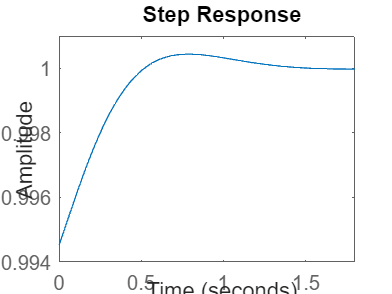


step(ss(ACL,BCL,CCL,DCL))